## Convective Heat Transfer

### Balance equation


$$m c_p \frac{dT}{dt}=UA(T_a-T) + \alpha Q$$


With the temperature initially at ambient temperature (TaTa), simulate the change in temperature over the 5 minutes when heater *Q* is adjusted to 50%. Use values of *m*=0.004 kg, *A*=0.0012 m2, cpcp=500 J/kg-K, and TaTa=23 oC. Compare the simulated temperature response to data from the TCLab. Add a simulation prediction to the script below to compare with the TCLab data.

### Step Response Code

% clear
clc; clear all; close all;

filename = "TCLab_data.csv";



try % try to read from file first
    A = readmatrix(filename)
    tm = A(:,1);
    T1 = A(:,2);
    
catch % if file can not be found, simulate
    try 
        % initialize lab
        lab = tclab;
        
        % loop through
        T1 = zeros(301, 1);
        tm = zeros(301, 1);
        lab.Q1(50);
        tic;
        for i=1:301;
            tm(i) = toc;
            T1(i) = lab.T1;
            pause(1);
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm T1]
        writematrix(A, filename, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

A =     0.0009   31.5738
    1.3329   31.4272
    2.4469   31.2805
    3.5841   31.3294
    4.7102   31.2317
    5.8202   31.2805
    6.9385   31.2805
    8.0541   31.3294
    9.1742   31.1828
   10.2927   31.3783


### Simulation and Plot

t = linspace(0, 300, 301);

[tt, Temp] = ode45(@(tt, Temp) convection_sim(tt, Temp), t, 23);

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

Q = 50

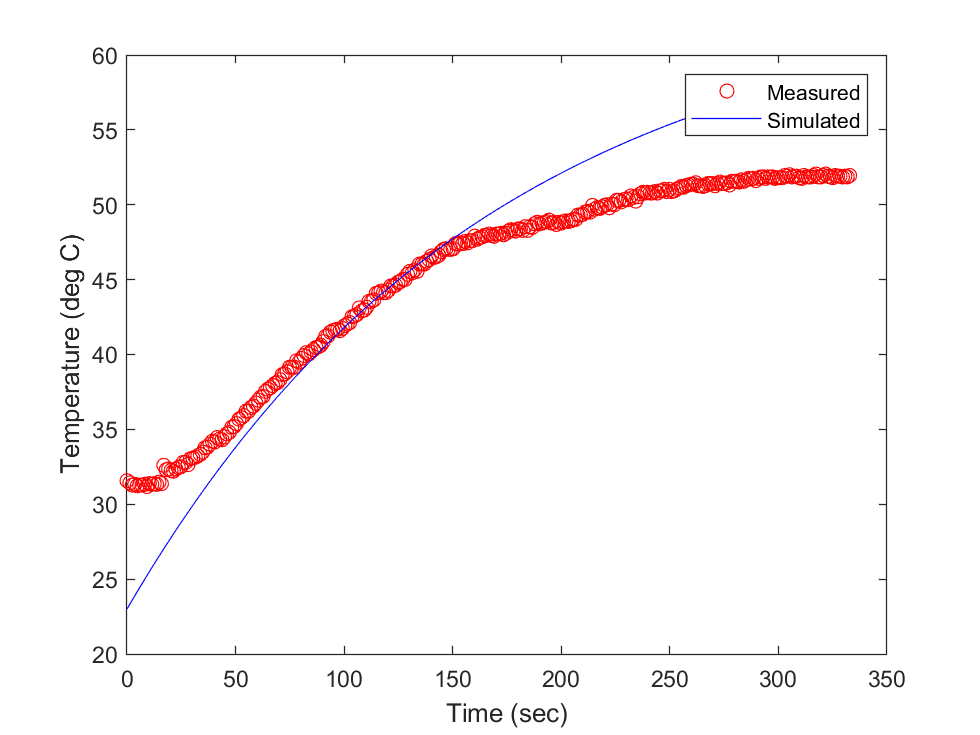


% Plot
plot(tm, T1, 'r.')
hold on;
plot(tt, Temp, 'b-')
hold off;
xlabel('Time (sec)')
ylabel('Temperature (deg C)')
legend({'Measured', 'Simulated'})

function dTdt = convection_sim(tt, Temp)
    U = 10;  % heat transfer (W/m^2 K)
    Ta = 23;  % Ambient Temperature (deg C)
    A = .0012;  % Area (m^2)
    m = .004;  % Mass (Kg)
    cp = 500;  % heat capacity (J / Kg K)
    alpha = .01;  % (W/%)
    Q = 50;  % percent power (%)
    dTdt = (U*A*(Ta-Temp)+alpha*Q)/(m * cp);
    
end